## Minimum Time

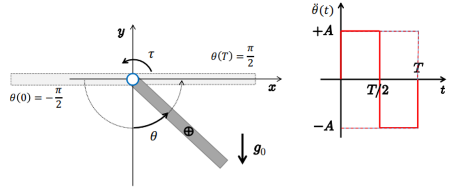

syms q1 dq1 I1 m1 d1 g0

% Inertia matrix
x1 = d1*sin(q1)

$$x1 = d_{1}\,\sin\left(q_{1}\right)$$

y1 = d1*cos(q1)

$$y1 = d_{1}\,\cos\left(q_{1}\right)$$


vx1 = diff(x1, q1)*dq1;
vy1 = diff(y1, q1)*dq1;

T_tr = simplify(0.5*m1*[vx1 vy1]*[vx1; vy1;] + m1*d1^2, steps=100)

$$T\_tr = \frac{{d_{1}}^{2}\,m_{1}\,\left({{\mathrm{dq}}_{1}}^{2}+2\right)}{2}$$

T_rot = 0.5*I1*dq1^2;
T = simplify(T_tr+T_rot,steps=100)

$$T = \frac{I_{1}\,{{\mathrm{dq}}_{1}}^{2}}{2}+\frac{{d_{1}}^{2}\,m_{1}\,\left({{\mathrm{dq}}_{1}}^{2}+2\right)}{2}$$


M11 = diff(diff(T, dq1), dq1);

M = [M11;];

M = simplify(M);

disp('The inertia matrix M(q) is:');

The inertia matrix M(q) is:


disp(M);

$$m_{1}\,{d_{1}}^{2}+I_{1}$$


% Potential Energy and Gravity Terms
U1 = m1*g0*d1*cos(q1);
U = [U1];
g_q = simplify([diff(U,q1);], Steps=100)

$$g\_q = -d_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$


% using the Christoffel symbols for a 3-DOF system
q  = [q1;];
dq = [dq1;];

% Inizializza la matrice C(q, dq) (3x3) a zeri simbolici:
C = sym(zeros(1,1));

% Formula dei coefficienti di Christoffel:
%   C(i,j) = 1/2 * SUM_k [ dM(i,j)/dq_k + dM(i,k)/dq_j - dM(k,j)/dq_i ] * dq_k
% Poi il vettore c(q,dq) = C(q,dq) * dq
for i = 1:1
    for j = 1:1
        % Costruisco ogni elemento C(i,j):
        tmp = 0;
        for k = 1:1
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

% Finalmente calcolo il vettore c(q, dq):
c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$0$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$0$$


disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$0$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$0$$